clear
close all
clc

## Variabler

%% Indtast geometriske variabler
a = 0.0065; % [m] Bredde af sakse link
h = 0.004; % [m] Tykkelse af stang
b_lang = 0.057; % [m] Længde af lang sakse link
b_kort = 0.032; % [m] Længde af kort sakse link
r_pin = 0.002; % [m] Pin radius i rotationspunkter
d_closed = 0.007; % [m] Midtpunktsafstanden når saksen er lukket
d_open = 0.047; % [m] Midtpunktsafstanden når saksen er lukket
L = 0.025; % [m] Længden mellem hvert punkt
k = 13; % Antal punkter for saksemekanismen
n_stang = 7; % Antal stænger
hul = 0.004; % [m] Hul diameter i stang

%% Masse
m_lang = 0.00205; % [kg] Vægt af lang sakse link uden huller (solid)
m_kort = 0.00115; % [Kg] Vægt af kort sakse link uden huller (solid)
m_blok1 = 0.0312437; % [kg] Vægt af en carrier med et sakseled (i top og bund)
m_blok2 = 0.040612; % [kg] Vægt af drevne carrier med et sakseled (i top og bund)

%% Indtast hastighed og acceleration
a_acc = 0.2; % [m/s^2] % Denne kombination af acc % velocity giver en tid på 4.3s
v_max = 0.06; % [m/s]

%% Flydspænding POM C
Sy = 60.67; % [MPa]

%% Endurance limit POM C
Se = 22.753; % [MPa] Endurance limit af POM C

% Formel til at finde Cycles to failure for en given spænding
% Baseret på denne artikel https://www.sciencedirect.com/science/article/pii/S003238611630204X#fd17
C_n = 0.07; % Tabel værdi fra artikel for injection molded Nylon66 semicrystalline
m_n = 0.36; % Tabel værdi fra artikel for injection molded Nylon66 semicrystalline

Sa = 22.753; % [MPa] Hvis det ønskes at kende antal cycles to failure for en given spænding

Nf_calc = (-(1/C_n) * log((Sa-Se)/(Sy-Se)))^(1/m_n);

% Til at lave log graf (S-N kurve)
% Nf = linspace(1, 1e7, 1e7);
Nf = 237600; % Antal cycles for 3 års brug
sigma_a = Se + (Sy - Se) * exp(-C_n*(Nf).^m_n);



%% Friktion
mu_r = 0.2; % [-] Rotations friktion POM mod stål
mu_s = 0.1; % [-] Translations friktion IGLIDUR mod stål

%% Tyngdekraft
g = 9.82; % [m/s^2]

%% Step size
step_size = 0.01; % [s] Tid pr. step.

%% Animation
Animation = 0; % 0 = Ingen animation, 1 = Generer animation



## Fatigue of POM-C

% plot(Nf, sigma_a)
% xscale('log')
% grid on
% sigma_a(1e5)

% Regner vinkel ud fra givne afstande
theta = acos(d_open/(2*L)) : 0.002 : acos(d_closed/(2*L));

% Matricer der indeholder hvert punkts koordinater ved en given vinkel:
i = 1;
punktx = zeros(k,length(theta));
punkty = zeros(k,length(theta));

while i <= k

    if mod(i,2) == 1
        punktx(i,:) = (i-1)*L*cos(theta);
        punkty(i,:) = 0;
    else
        if mod(i,4) == 2
            punktx(i,:) = (i-1)*L*cos(theta);
            punkty(i,:) = L*sin(theta);
        elseif mod(i,4) == 0
            punktx(i,:) = (i-1)*L*cos(theta);
            punkty(i,:) = -L*sin(theta);
        end
    end

    i = i + 1;
end


## Definer hastighed og acceleration

s_m = ((k-1)/2)*(d_open - d_closed); % Strækning punktet m flyttes

t_acc = v_max/a_acc; % [s] Tid for at opnå maksimal hastighed
s_acc = (v_max)^2/(2*a_acc); % [m] Strækning til at opnå maksimal hastighed
s_kon = (s_m - s_acc*2); % [m] Strækning med konstant hastighed
t_kon = (s_kon)/v_max; % [s] Tid ved konstant hastighed
T = t_acc*2 + t_kon; % [s] Total tid

% Finder hastigheden af m ved given tidspunkt
t = 0 : step_size : T;

v = zeros(size(t));

% Acceleration
idx1 = (t >= 0) & (t < t_acc);
v(idx1) = a_acc .* t(idx1);

% Konstant hastighed
idx2 = (t >= t_acc) & (t < t_acc + t_kon);
v(idx2) = v_max;

% Deceleration
idx3 = (t >= t_acc + t_kon) & (t <= T);
v(idx3) = v_max - a_acc .* (t(idx3) - t_acc - t_kon);

% Finder positionen af punktet m som funktion af tiden

x_m0 = (n_stang-1)*d_closed; % [m] Start positionen af m

x_t = zeros(size(t));

% Acceleration
idx1 = (t >= 0) & (t < t_acc);
x_t(idx1) = 1/2 * a_acc * (t(idx1)).^2;

% Konstant hastighed
idx2 = (t >= t_acc) & (t < t_acc + t_kon);
x_t(idx2) = s_acc + (v_max * (t(idx2) - t_acc));

% Deceleration
idx3 = (t >= t_acc + t_kon) & (t <= T);
x_t(idx3) = (s_kon + s_acc + v_max * (t(idx3)-t_acc-t_kon)) - 1/2 * a_acc * (t(idx3)-t_acc-t_kon).^2;

x_t = x_t + x_m0;

% Definerer theta som funktion af tiden
theta_t = acos(x_t/(12*L));

% Vinkelhastighed og vinkelacceleration

a_m = zeros(size(t));

% Acceleration
idx1 = (t >= 0) & (t < t_acc);
a_m(idx1) = +a_acc;

% Konstant hastighed
idx2 = (t >= t_acc) & (t < t_acc + t_kon);
a_m(idx2) = 0;

% Deceleration
idx3 = (t >= t_acc + t_kon) & (t <= T);
a_m(idx3) = -a_acc;

omega = -v ./ (12*L*sin(theta_t));
alpha = -(a_m + 12*L*cos(theta_t).*omega.^2) ./ (12*L*sin(theta_t));

## Hastighedsanalyse

% Matricer med hastighederne i x og y-retningen for hvert punkt
v_x = zeros(k,length(theta_t));
v_y = zeros(k,length(theta_t));


for i = 1:k
    if mod(i,2) == 1
        v_x(i,:) = -(i-1)*L*sin(theta_t).*omega;
        v_y(i,:) = 0;
    else
        if mod(i,4) == 2
            v_x(i,:) = -(i-1)*L*sin(theta_t).*omega;
            v_y(i,:) = L*cos(theta_t).*omega;
        elseif mod(i,4) == 0
            v_x(i,:) = -(i-1)*L*sin(theta_t).*omega;
            v_y(i,:) = -L*cos(theta_t).*omega;
        end
    end
end

## Accelerationsanalyse

% Matricer med acceleration i x og y-retningen for hvert punkt
a_x = zeros(k,length(theta_t));
a_y = zeros(k,length(theta_t));

for i = 1:k
    if mod(i,2) == 1
        a_x(i,:) = -(i-1)*L*(cos(theta_t).*omega.^2 + sin(theta_t).*alpha);
        a_y(i,:) = 0;
    else
        if mod(i,4) == 2
            a_x(i,:) = -(i-1)*L*(cos(theta_t).*omega.^2 + sin(theta_t).*alpha);
            a_y(i,:) = L*(cos(theta_t).*alpha - sin(theta_t).*omega.^2);
        elseif mod(i,4) == 0
            a_x(i,:) = -(i-1)*L*(cos(theta_t).*omega.^2 + sin(theta_t).*alpha);
            a_y(i,:) = -L*(cos(theta_t).*alpha - sin(theta_t).*omega.^2);
        end
    end
end

% Positioner som funktion af TID (theta_t, ikke theta)
punkt_xt = zeros(k, length(t));
punkt_yt = zeros(k, length(t));

for i = 1:k
    if mod(i,2) == 1
        punkt_xt(i,:) = (i-1)*L*cos(theta_t);
        punkt_yt(i,:) = 0;
    elseif mod(i,4) == 2
        punkt_xt(i,:) = (i-1)*L*cos(theta_t);
        punkt_yt(i,:) =  L*sin(theta_t);
    elseif mod(i,4) == 0
        punkt_xt(i,:) = (i-1)*L*cos(theta_t);
        punkt_yt(i,:) = -L*sin(theta_t);
    end
end

## Acceleration transformeret til lokalt koordinatsystem

%% Lokal koordinat transformation — generaliseret

% Hvilke globale punkter tilhører hver stang
stang_pts = {[1,2], [2,3,4], [4,5,6], [6,7,8], [8,9,10], [10,11,12], [12,13]};

% Stangens vinkel: ulige stænger = theta_t, lige = pi-theta_t
stang_vinkel = cell(n_stang, 1);
for s = 1:n_stang
    if mod(s,2) == 1
        stang_vinkel{s} = theta_t;
    else
        stang_vinkel{s} = pi - theta_t;
    end
end

% Beregn lokale accelerationer for alle stænger
stang_lok_perp  = cell(n_stang, 1);   % Vinkelret på stang (bøjning)
stang_lok_axial = cell(n_stang, 1);   % Langs stang (træk/tryk)

for s = 1:n_stang
    pts = stang_pts{s};
    phi = stang_vinkel{s};
    np  = length(pts);

    stang_lok_perp{s}  = zeros(np, length(t));
    stang_lok_axial{s} = zeros(np, length(t));

    for ii = 1:np
        p = pts(ii);
        stang_lok_perp{s}(ii,:)  = -a_x(p,:).*sin(phi) + a_y(p,:).*cos(phi);
        stang_lok_axial{s}(ii,:) =  a_x(p,:).*cos(phi) + a_y(p,:).*sin(phi);
    end
end

## Kraft beregninger

%Inertimoment af sakse stænger
m_hul = 0.00007; % [kg] Tilsvarende masse af hul i stængerne
I_hul_center = 1/2 * m_hul * (hul/2)^2; % Inertimoment af hul der roterer om sin center akse.
I_hul = I_hul_center + m_hul*L^2; % Parallel axis theorem til at find inertimoment for hul der roterer omkring anden akse

I_lang_solid = 1/12 * m_lang * (a^2+b_lang^2); % [kg*m^2] Inertimoment af lang solid sakse link
I_lang = I_lang_solid - I_hul_center - 2*I_hul; % [kg*m^2] Inertimoment af lang sakse link med huller

I_kort_solid = 1/12 * m_kort * (a^2+b_kort^2); % [kg*m^2] Inertimoment af kort sakse link
I_kort = I_kort_solid - 2*I_hul; % [kg*m^2] Inertimoment af kort sakse link med huller

% Finder massemidtpunkts acceleration for de korte stænger
% Stang 1
a_g_x_1 = (a_x(1,:) + a_x(2,:))/2;
a_g_y_1 = (a_y(1,:) + a_y(2,:))/2;

% Stang 7
a_g_x_7 = (a_x(12,:) + a_x(13,:))/2;
a_g_y_7 = (a_y(12,:) + a_y(13,:))/2;

## Beregner inertikræfter

F_x = zeros(n_stang, length(t));
F_y = zeros(n_stang, length(t));
M = zeros(n_stang, length(t));

idx = [3 5 7 9 11];

for i = 1:n_stang
    if i == 1
        F_x(i, :) = m_kort * a_g_x_1.'; 
        F_y(i, :) = m_kort * a_g_y_1.';  
    elseif i == 7
        F_x(i, :) = m_kort * a_g_x_7.'; 
        F_y(i, :) = m_kort * a_g_y_7.';
    else
        F_x(i, :) = m_lang * a_x(idx(i-1), :);
        F_y(i, :) = m_lang * a_y(idx(i-1), :);
    end
end

for i = 2:6 
    pt = idx(i-1);
    F_x(i,:) = F_x(i,:) + (m_blok1/2) * a_x(pt, :); % Halv masse da saksen i bunden også tager en del af lasten
end

F_x(7, :) = F_x(7,:) + (m_blok2/2) * a_x(13,:); % Halv masse da saksen i bunden også tager en del af lasten

% Ret i beregningen af M:
stang_alpha_fortegn = [1, -1, 1, -1, 1, -1, 1];  % ulige=+1, lige=-1
for s = 1:n_stang
    if s == 1 || s == 7
        I_s = I_kort;
    else
        I_s = I_lang;
    end
    M(s,:) = stang_alpha_fortegn(s) * I_s * alpha;
end 

## kræfter

%% ── Konstanter ──────────────────────────────────────────────────────────
n_eq  = n_stang*3 + 5;   % 21 Newton-Euler + 5 slider-bindinger = 26
n_unk = k*2;              % 13 punkter × 2 retninger = 26 ubekendte

% Slider-punkterne c(3), e(5), g(7), i(9), k(11) har ingen x-kraft.
% Deres x-kolonne i A: 2*punktindex - 1
slider_pts  = [3, 5, 7, 9, 11];
slider_xcol = 2*slider_pts - 1;   % = [5, 9, 13, 17, 21]
stang_reak = {[1,2,3,4], [3,4,5,6,7,8], [7,8,9,10,11,12], [11,12,13,14,15,16], [15,16,17,18,19,20], [19,20,21,22,23,24], [23,24,25,26]};
 
X_loesning = zeros(n_unk, length(t));
X_loesning_korr = zeros(n_unk, length(t));


for j = 1:length(t)

    %% ── TRIN 1: B-vektor ────────────────────────────────────────────────
    % B: [Fx(s1); Fy(s1); M(s1); Fx(s2); ...] + 5 nuller for slider-bindinger
    B_full = [reshape([F_x(:,j), F_y(:,j), M(:,j)]', [], 1);
              zeros(5,1)];

    %% ── TRIN 2: Initialisér A og fortegnsstyring ─────────────────────
    A = zeros(n_eq, n_unk);

    brugte_cols = [];
    

    for s = 1:n_stang

        %% ── TRIN 3: Rækkerne og CM for denne stang ─────────────────────
        row_Fx = (s-1)*3 + 1;
        row_Fy = (s-1)*3 + 2;
        row_M  = (s-1)*3 + 3;

        % Massemidtpunktets koordinater
        if s == 1
            % Kort stang S1 (a–b): CM = midpunkt
            cm_x = (punkt_xt(1,j) + punkt_xt(2,j)) / 2;
            cm_y = (punkt_yt(1,j) + punkt_yt(2,j)) / 2;
        elseif s == 7
            % Kort stang S7 (l–m): CM = midpunkt
            cm_x = (punkt_xt(12,j) + punkt_xt(13,j)) / 2;
            cm_y = (punkt_yt(12,j) + punkt_yt(13,j)) / 2;
        else
            % Lang stang S2–S6: CM = det midterste tap (indeks 2 i stang_pts)
            cm_pt = stang_pts{s}(2);
            cm_x  = punkt_xt(cm_pt, j);
            cm_y  = punkt_yt(cm_pt, j);
        end

        %% ── TRIN 4: Fyld kraft- og momentrækker ─────────────────────────
        cols = stang_reak{s};

        for c = 1:length(cols)
            col = cols(c);

            % Fortegn: delt tap med forrige stang → Newton's 3. lov → −1
            if ismember(col, brugte_cols)
                f = -1;
            else
                f = +1;
            end

            % Punktets fysiske koordinater
            pt_idx = ceil(col / 2);          % hvilken punkt (1–13)
            px_pt  = punkt_xt(pt_idx, j);
            py_pt  = punkt_yt(pt_idx, j);

            if mod(col, 2) == 1
                %% X-kraft kolonne
                % ΣFx: koefficient = fortegn
                A(row_Fx, col) = f;

                A(row_M, col) = f * (-(py_pt - cm_y));

            else
                %% Y-kraft kolonne
                % ΣFy: koefficient = fortegn
                A(row_Fy, col) = f;

                A(row_M, col) = f * (+(px_pt - cm_x));
            end
        end

        brugte_cols = unique([brugte_cols, cols]);

    end  % stang-løkke

    %% ── TRIN 5: Slider-bindinger (rækker 22–26) ─────────────────────────
    for si = 1:5
        A(n_stang*3 + si, slider_xcol(si)) = 1;
    end

    
    if abs(v(j)) < 1e-8
        sgn = -1;
    else
        sgn = -sign(v(j));
    end  
    

    for si = 1:5
        row   = n_stang*3 + si;
        col_x = slider_xcol(si);
        col_y = 2*slider_pts(si);
        v_si = v_x(slider_pts(si), j);

        if abs(v_si) < 1e-5
            sgn_si = sign(v(j));
            if sgn_si == 0; sgn_si = 1; end
        else
            sgn_si = sign(v_si); 
        end
      

        A(row, col_x) = 1;
        B_full(row) = -mu_s * m_blok1 * g * sgn_si;
    end


    %% Brug forrige tidssteps kræfter til pin-friktion
    if j == 1 || j == 2
        X_fric = zeros(n_unk, 1);
    else
        X_fric = X_loesning(:, j-1);
    end
    
    M_fric_led = zeros(k, 1);
    for p = 1:k
        M_fric_led(p) = mu_r * r_pin * sqrt(X_fric(2*p-1)^2 + X_fric(2*p)^2);
    end
    
    B_fric = B_full;
    for s = 1:n_stang
        pts_s = stang_pts{s};
        B_fric(3*s) = B_fric(3*s) + stang_alpha_fortegn(s) * sgn * sum(M_fric_led(pts_s));
    end
    
    X = A \ B_fric; 
    
    B_full_korr = B_fric;

    for si = 1:5
        row   = n_stang*3 + si;
        col_y = 2*slider_pts(si);
        v_si = v_x(slider_pts(si), j);

        if abs(v_si) < 1e-5
            sgn_si = sign(v(j));
            if sgn_si == 0; sgn_si = 1; end
        else
            sgn_si = sign(v_si); 
        end

        Fcy_nu = X(col_y);
        N_si = abs(Fcy_nu) + m_blok1 * g;
        B_full_korr(row) = -mu_s * N_si * sgn_si;
    end


    X_korr = A \ B_full_korr;

X_loesning(:, j) = X;
X_loesning_korr(:,j) = X_korr;
end

## POST PROCESS OG SPÆNDINGER

%% ── POST-PROCESS: stangkrafter og spænding ────────────────────────────
sigma_vm  = zeros(n_stang, length(t));   
sigma_vm_net  = zeros(n_stang, length(t));  
sigma_vm_Kt  = zeros(n_stang, length(t));

% --- tværsnitsdata ---
A_kort = a * h;
A_lang = a * h;
A_net = a * h - h * hul;

I_area_kort = (h * a^3)/12;
I_area_lang = (h * a^3)/12;
I_area_net = (h*(a^3 - hul^3))/12;

c_geom = a/2;   % neutral fiber afstand

% Spændingskoncentrationsfaktor
W   = a;       % pladebredde = rod-bredde [m]
r   = hul / W; % = 0.6154

Kt = 3.0039 - 3.753*r + 7.9735*r^2 - 9.2659*r^3 + 1.8145*r^4 + 2.9684*r^5;


for j = 1:length(t)

    X = X_loesning_korr(:,j);

    for s = 1:n_stang

        pts = stang_pts{s};

        %% --- geometri ---
        p1 = pts(1);
        p2 = pts(end);

        x1 = punkt_xt(p1,j);  y1 = punkt_yt(p1,j);
        x2 = punkt_xt(p2,j);  y2 = punkt_yt(p2,j);

        dx = x2 - x1;
        dy = y2 - y1;

        L_stang = sqrt(dx^2 + dy^2);

        ex = dx / L_stang;
        ey = dy / L_stang;

        %% --- knudekræfter ---
        Fx1 = 0; Fy1 = 0;
        Fx2 = 0; Fy2 = 0;

        for k_col = 1:length(stang_reak{s})
            col    = stang_reak{s}(k_col);
            pt     = ceil(col/2);
        
            % Samme fortegnsregel som A-matricen:
            % p1 for s>=2 er delt med forrige stang → fortegn -1
            if pt == p1 && s >= 2
                f_sign = -1;
            else
                f_sign = +1;
            end
        
            if mod(col,2) == 1
                Fx = f_sign * X(col);  Fy = 0;
            else
                Fx = 0;  Fy = f_sign * X(col);
            end
        
            if pt == p1
                Fx1 = Fx1 + Fx;  Fy1 = Fy1 + Fy;
            elseif pt == p2
                Fx2 = Fx2 + Fx;  Fy2 = Fy2 + Fy;
            end
        end

        %% --- lokalt koordinatsystem ---
        % aksialkraft
        N1 = Fx1*ex + Fy1*ey;
        N2 = Fx2*ex + Fy2*ey;

        N = max(abs([N1 N2])); %max([N1 N2]


        V1 = -Fx1*ey + Fy1*ex;
        V2 = -Fx2*ey + Fy2*ex;

        V = max(abs([V1 V2])); %max([V1 V2]); 

        %% --- bøjningsmoment (approximation) ---
        M1 = V1 * L_stang / 2;
        M2 = V2 * L_stang / 2;

        M = max(abs([M1, M2])); %max([M1 M2]);
        

        %% --- tværsnit ---
        if ismember(s, [1, n_stang])
            A_cs = A_kort;
            Izz  = I_area_kort;
        else
            A_cs = A_lang;
            Izz  = I_area_lang;
        end

        %% --- spænding (ægte von Mises inkl. shear) ---

        sigma_ax = N / A_cs;
        sigma_b  = M * c_geom / Izz;
        tau_xy   = 1.5 * (V / A_cs);

        sigma_ax_net = N / A_net;
        sigma_b_net  = M * c_geom / I_area_net;
        tau_xy_net   = 1.5 * (V / A_net);
        
        %% Punkt 1: Top/bund-fiber (maks bøjning, τ = 0)
        sigma_vm_fiber = sigma_ax + sigma_b;

        % Ved hul tværsnit
        sigma_vm_fiber_net = sigma_ax_net + sigma_b_net;

        % Med Kt
        sigma_vm_fiber_net_Kt = Kt * sigma_ax_net + Kt * sigma_b_net;

        %% Punkt 2: Neutralaksen (maks τ, σ_b = 0)
        sigma_vm_neutral = sqrt(sigma_ax^2 + 3*tau_xy^2);

        % Ved hul tværsnit
        sigma_vm_neutral_net = sqrt(sigma_ax_net^2 + 3*tau_xy_net^2);
        
        % Med Kt
        sigma_vm_neutral_net_Kt = sqrt((Kt * sigma_ax_net)^2 + 3*(Kt * tau_xy_net)^2);

        %% Korrekt von Mises = det værste af de to
        sigma_vm(s,j) = max(sigma_vm_fiber, sigma_vm_neutral);

        % Ved hul tværsnit
        sigma_vm_net(s,j) = max(sigma_vm_fiber_net, sigma_vm_neutral_net);

        % Med Kt
        sigma_vm_Kt(s,j) = max(sigma_vm_fiber_net_Kt, sigma_vm_neutral_net_Kt);

    end
end

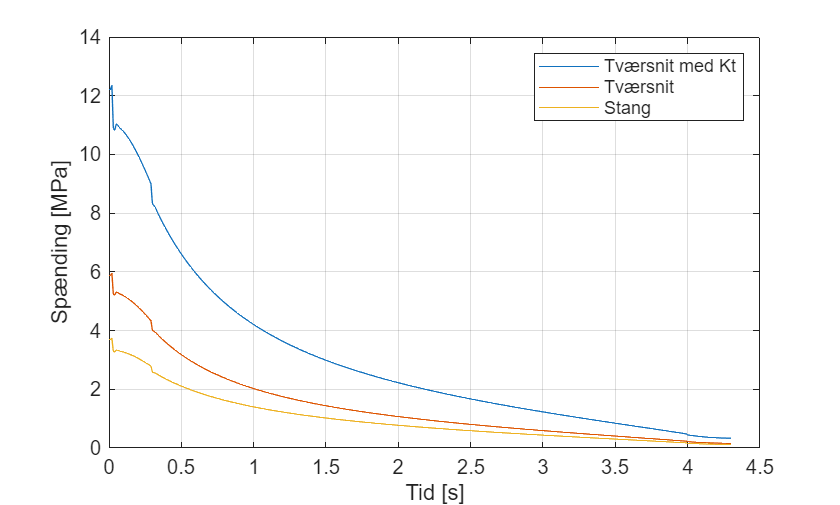

figure(10)
plot(t, max(sigma_vm_Kt)/1e6)
ylabel('Spænding [MPa]')
xlabel('Tid [s]')
grid on
hold on
plot(t, max(sigma_vm_net)/1e6)
plot(t, max(sigma_vm)/1e6)
hold off
legend('Tværsnit med Kt', 'Tværsnit', 'Stang')

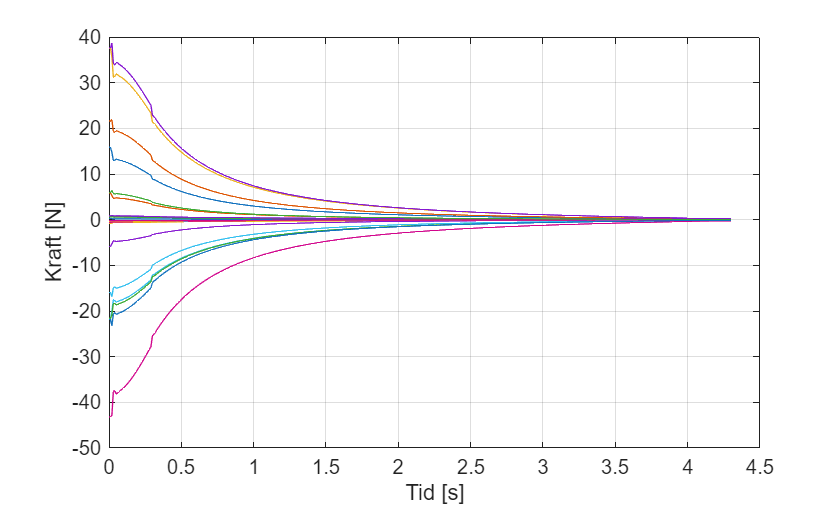

figure(11)
plot(t, X_loesning_korr)
ylabel('Kraft [N]')
xlabel('Tid [s]')
grid on

fprintf('Maks spænding stang: %.6f MPa\n', max(abs(sigma_vm(:)/1e6)));

Maks spænding stang: 3.736524 MPa


fprintf('Maks spænding ved hul tværsnit: %.6f MPa\n', max(abs(sigma_vm_net(:)/1e6)));

Maks spænding ved hul tværsnit: 5.951585 MPa


fprintf('Maks spænding ved hul tværsnit med Kt: %.6f MPa\n', max(abs(sigma_vm_Kt(:)/1e6)));

Maks spænding ved hul tværsnit med Kt: 12.359857 MPa


fprintf('Acceleration: %.6f m/s^2\n', a_acc);

Acceleration: 0.200000 m/s^2


fprintf('Total tid: %.6f s\n', T);

Total tid: 4.300000 s


## Motormoment

p = 0.004; % [m] Pitch af spindelskrue
eta = 0.2; % [-] Virkningsgrad af spindelskrue

F_sp = 2*abs(X_loesning_korr(25,:)) + mu_s * (abs(X_loesning_korr(26,:)) + m_blok2*g);

% Motor torque
T_m = (max(abs(F_sp)) * p) / (2*pi*eta)

T_m = 0.0080

% RPM
RPM = (s_m/p)/T

RPM = 13.9535

## Animeret spændingsplot

if Animation == 1
    %% Animeret plot: Saksemekanisme med von Mises-spændinger
    %  Forudsætter at følgende variable eksisterer i workspace:
    %    punkt_xt, punkt_yt  [k x length(t)]  - punktkoordinater
    %    VM_stang            [n_stang x length(t)] - von Mises spænding [Pa]
    %    stang_pts           {cell}           - punktindeks per stang
    %    t                   [1 x length(t)]  - tidsarray
    %    theta_t             [1 x length(t)]  - vinkel [rad]
    %    n_stang             skalar           - antal stænger

    %% ── Parametre ──────────────────────────────────────────────────────────
    n_frames    = 120;        % ønsket antal animationsframes
    pause_tid   = 0.035;       % sekunder mellem frames

    %% ── Beregn farve-skala ─────────────────────────────────────────────────
    VM_MPa       = sigma_vm_Kt/ 1e6;        % konverter til MPa
    sigma_max    = max(VM_MPa(:));
    sigma_min    = 0;

    % Aksegrænser fra position-data (i mm)
    x_alle = punkt_xt(:) * 1000;
    y_alle = punkt_yt(:) * 1000;
    x_lim  = [min(x_alle) - 5,  max(x_alle) + 5];
    y_lim  = [min(y_alle) - 10, max(y_alle) + 10];

    %% ── Farvepalette og skip-faktor ────────────────────────────────────────
    cmap = jet(256);
    skip = max(1, floor(length(t) / n_frames));
    frames_idx = 1:skip:length(t);

    %% ── Figur-opsætning ────────────────────────────────────────────────────
    fig = figure('Color', 'w', 'Position', [100 80 900 500]);
    colormap(cmap);

    for k_frame = 1:length(frames_idx)
        j = frames_idx(k_frame);
        cla; hold on;

        %% Tegn stænger med farve efter spænding
        for s = 1:n_stang
            pts   = stang_pts{s};
            x_pts = punkt_xt(pts, j) * 1000;   % mm
            y_pts = punkt_yt(pts, j) * 1000;   % mm

            % Normaliser spænding → farveindeks [1 … 256]
            if sigma_max > 0
                n = (VM_MPa(s, j) - sigma_min) / (sigma_max - sigma_min);
            else
                n = 0;
            end
            n       = max(0, min(1, n));
            c_idx   = max(1, round(n * 255) + 1);
            farve   = cmap(c_idx, :);

            plot(x_pts, y_pts, '-', 'Color', farve, 'LineWidth', 6);

            % Vis spændingsværdi midt på stangen
            x_mid = mean(x_pts);
            y_mid = mean(y_pts);
            text(x_mid, y_mid + 2, sprintf('%.1f', VM_MPa(s, j)), ...
                'FontSize', 7, 'HorizontalAlignment', 'center', ...
                'Color', 0.2*[1 1 1]);
        end

        %% Tegn led-punkter
        scatter(punkt_xt(:, j) * 1000, punkt_yt(:, j) * 1000, ...
            30, 'k', 'filled', 'MarkerEdgeColor', 'none');

        %% Markér drivpunkt m
        plot(punkt_xt(end, j) * 1000, punkt_yt(end, j) * 1000, ...
            'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

        %% Formatering
        axis equal;
        xlim(x_lim);
        ylim(y_lim);
        grid on; box on;
        xlabel('x [mm]', 'FontSize', 11);
        ylabel('y [mm]', 'FontSize', 11);

        theta_deg    = theta_t(j) * 180 / pi;
        max_s_nu     = max(VM_MPa(:, j));
        [~, s_krit]  = max(VM_MPa(:, j));

        title(sprintf('t = %.3f s   |   \\theta = %.1f°   |   Max \\sigma_{VM} = %.2f MPa (stang %d)', ...
            t(j), theta_deg, max_s_nu, s_krit), 'FontSize', 10);

        %% Farvelinje
        clim([sigma_min, sigma_max]);
        cb = colorbar('Location', 'eastoutside');
        ylabel(cb, '\sigma_{VM} [MPa]', 'FontSize', 10);

        drawnow;
    end
    fprintf('Maks spænding: %.2f MPa  (stang %d, tidsstep %d)\n', ...
        max(VM_MPa(:)), ...
        mod(find(VM_MPa == max(VM_MPa(:))) - 1, n_stang) + 1, ...
        ceil(find(VM_MPa == max(VM_MPa(:))) / n_stang));
end